# Multiclass Support Vector Machines

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the pump features and partitions it into training and testing

T = readtable("./data/pumpFeatures.csv");
rng(0)
cv = cvpartition(size(T, 1), "HoldOut", 0.3);
dataTrain = T(cv.training, :);
dataTest = T(cv.test, :)

dataTest = 300×85 table
    wMotor_mean    wMotor_std    wMotor_fftPeakIdx    wMotor_skewness    wMotor_kurtosis    wMotor_peak2peak    wMotor_peak2rms    wMotor_rms    wMotor_mad    wMotor_csRange    wMotor_pLow    wMotor_pMid    wMotor_pHigh    wMotor_pKur    iMotor_mean    iMotor_std    iMotor_fftPeakIdx    iMotor_skewness    iMotor_kurtosis    iMotor_peak2peak    iMotor_peak2rms    iMotor_rms    iMotor_mad    iMotor_csRange    iMotor_pLow    iMotor_pMid    iMotor_pHigh    iMotor_pKur    qIn_mean   

## Tasks 1 & 2

To construct a multiclass Support Vector Machine (SVM), use the `fitcecoc` function.

`msvmModel` `=` `fitcecoc``(``tableData``,``...`

    `"``ResponseVariable``"``)``;`

To set SVM model options, create a template learner by passing the property name-value pairs to the `templateSVM` function.

`t` `=` `templateSVM``(``"``PropertyName``"``,``PropertyValue``)``;`

Then provide the template learner to the `fitcecoc` function as the value for the `Learners` property.

`mdl` `=` `fitcecoc``(``tableData``,``"``Response``"``,``...`

        `"Learners"``,``t``)``;`

t = templateSVM("Standardize", true,...
    "KernelFunction", "polynomial");
mdlMSVM = fitcecoc(dataTrain, "faultCode",...
    "Learners", t);

Evaluate model

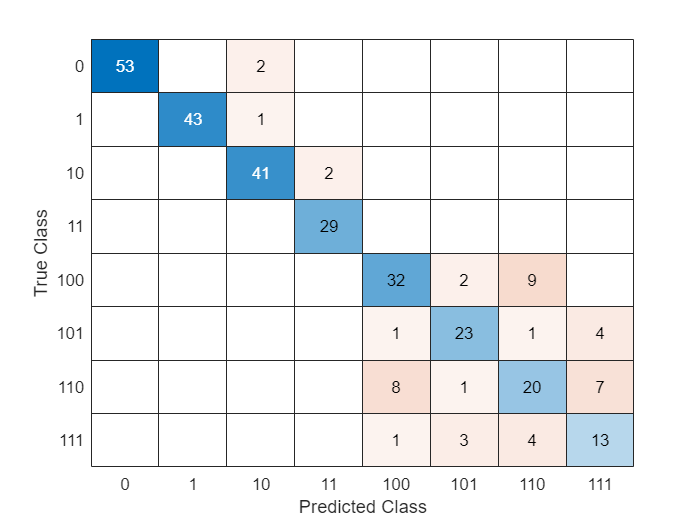

Training Error: 0
Loss: 0.16075


evalModel(dataTest, mdlMSVM)

Do not edit. This function is used to evaluate a model by displaying the confusion chart, training error, and test loss.

function evalModel(dataTest, mdl)
    confusionchart(dataTest.faultCode, predict(mdl, dataTest))
    disp("Training Error: " + resubLoss(mdl))
    disp("Loss: " + loss(mdl, dataTest))
end